# Neural Network 

General Methodology 

`1. Initialize parameters / Define hyperparameters `

`2. Loop for num_iterations: a. Forward propagation `

`b. Compute cost function c. Backward propagation `

`d. Update parameters (using parameters, and grads from backprop)  `

`3. Use trained parameters to predict labels`

`Structure for the network: linear -> relu --> linear -->sigmoid `

`Functions used:`

     `initialize_parameters``(``n_x``, ``n_h``, ``n_y``): ... ``return` `parameters`  

`     linear_activation_forward``(``A_prev``, ``W``, ``b``, ``activation``): ... ``return` `A``, ``cache`

     `compute_cost``(``AL``, ``Y``): ... ``return` `cost`

`     linear_activation_backward``(``dA``, ``cache``, ``activation``): ... ``return` `dA_prev``, ``dW``, ``db`

`    update_parameters``(``parameters``, ``grads``, ``learning_rate``): ... ``return` `parameters`

- Model Testing using data_new_extended  

clc;clear;
% load data 
%[train_x, train_y, test_x, test_y, classes] = load_data;

% load our data 
load featureData.mat 
ourdata = table2array(data)

ourdata = 	1.0e+03 *

    0.2402    1.4104   -0.0706    0.0042   -0.0018    0.0006    0.0004    0.0007   -0.0008    0.0008   -0.0004    0.0006    0.0004    0.0002   -0.0002    3.4147    0.0000    1.2860    0.0834   -0.0000   -0.0001         0
    0.2254    1.4246   -0.0566    0.0040   -0.0003   -0.0002   -0.0007   -0.0009   -0.0009   -0.0006   -0.0004    0.0000   -0.0001   -0.0001   -0.0002    4.5191    0.0000    1.5205    0.0673   -0.0000    0.0001         0
    0.2703    1.0437   -0.0515    0.0070   -0.0046   -0.0007   -0.0023    0.0002   -0.0019    0.0000   -0.0006   -0.0001    0.0005   -0.0002   -0.0002    1.8313    0.0000    0.5221    0.0919   -0.0000    0.0000         0
    0.2154    1.4104   -0.0524    0.0027   -0.0005   -0.0000   -0.0002    0.0002   -0.0007   -0.0000   -0.0003    0.0005   -0.0002    0.0003   -0.0004    5.9271    0.0000    1.2860    0.0834   -0.0000   -0.0001         0
    0.1627    1.4299   -0.0543    0.0038    0.0004    0.0005    0.0000   -0.0005   -0.0005   -

% normalize the data 
for i = 1: size(ourdata,2)-1 
        temp = ourdata(:,i);
        maximum = max(temp);
        minimum = min(temp);
        for j = 1:length(temp)
            temp(j) = (temp(j)-minimum )/(maximum - minimum);
        end 
        ourdata(:,i) = temp; 
end 
train_x = ourdata(:,size(ourdata,2)-1);
train_y = ourdata(:,size(ourdata,2));

% Explore dataset 
m_train = size(train_x,1);
% m_test = size(test_x,1);

fprintf ("Number of training examples: " + num2str(m_train));

Number of training examples: 166

%fprintf ("Number of testing examples: " + num2str(m_test));
fprintf ("train_x shape: " + num2str(size(train_x)));

train_x shape: 166    1

fprintf ("train_y shape: " + num2str(size(train_y)));

train_y shape: 166    1

%fprintf ("test_x shape: " + num2str(size(test_x)));
%fprintf ("test_y shape: " + num2str(size(test_y)));

## 2-Layer Neural Network

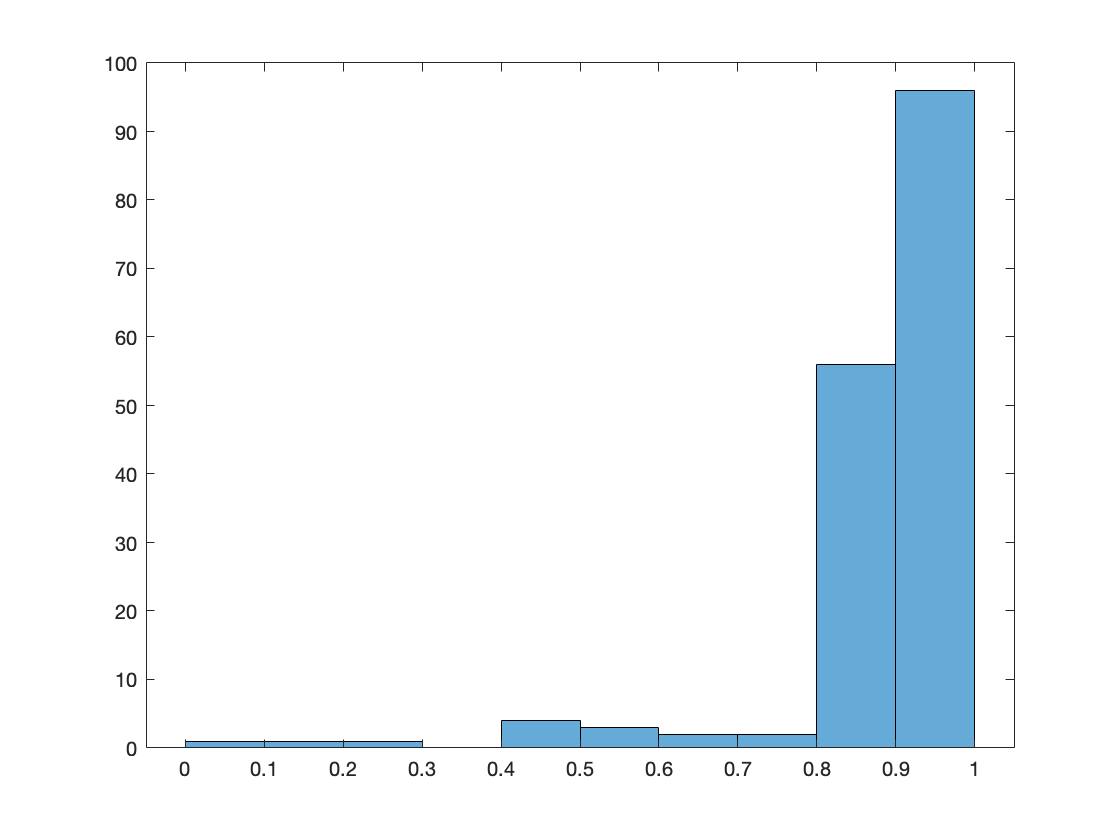

% roll, plot, scale the dataset 
train_x = train_x';
histogram(train_x(:,:));

train_y = train_y'

train_y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%CONSTANTS DEFINING THE MODEL
n_x = 22;     % 26 samples/input
n_h = 7 ;   % 7 hidden layers 
n_y = 1 ;   % 1 output 
layers_dims = [n_x, n_h, n_y];
parameters = two_layer_model(train_x, train_y, layers_dims, 0.00009, 166, true);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in linear_forward (line 14)
    Z = W*A+b;

Error in linear_activation_forward (

predictions_train = predict(train_x, train_y, parameters);
